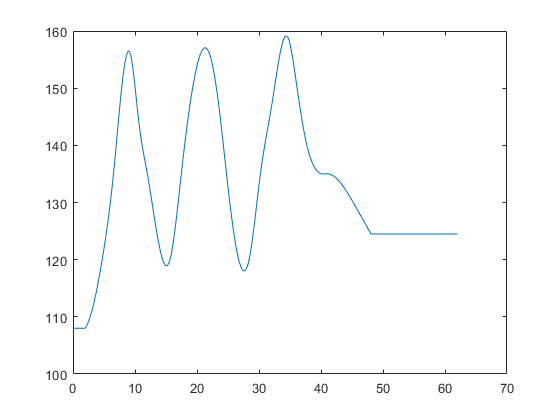

clear all 
clc
%%先生成速度随时间的变化序列
load vx
load path77
plot(vx_ref(:,3),vx_ref(:,1)*3);

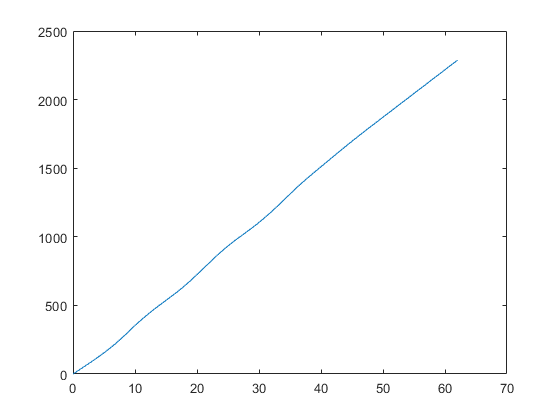


vx = vx_ref(:,1)*3/3.6;
T = vx_ref(:,3);
%对速度时间进行插值，得到更密致的速度序列。
% vx = interp1(X,vx_ref,T);
% plot(T,vx/3.6);
%对每一时间进行积分，得到x的序列
for i=1:1:length(T)
    x(i) = trapz(T(1:i),vx(1:i));
end
%得到x坐标后，根据x-y坐标之间的映射关系，得到y的坐标
x_ref = path5(:,1)*3.8;%%变化
y_ref = path5(:,2);
y = interp1(x_ref,y_ref,x);

diff_x = diff(x);
diff_x(end+1) = diff_x(end);
diff_y = diff(y);
diff_y(end+1) = diff_y(end);
%由x\y坐标得到横摆角坐标变化
yaw = atan2(diff_y,diff_x);
diff_yaw = diff(yaw);
diff_yaw(end+1) = diff_yaw(end);
yaw_rate = diff_yaw/0.15238;
plot(T,x);

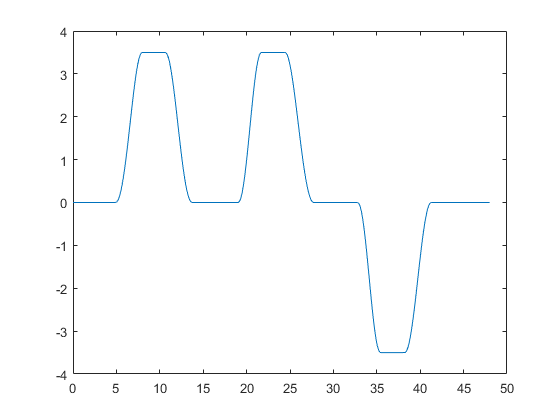

plot(T,y);

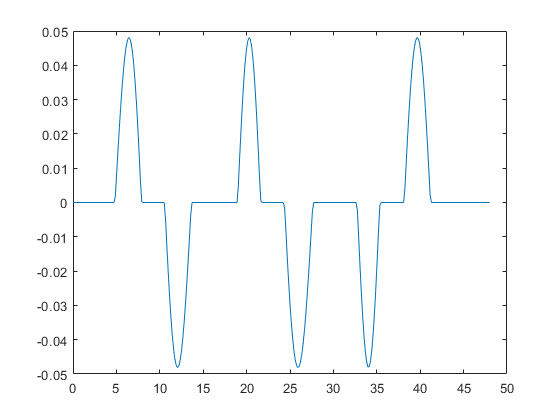

plot(T,yaw);

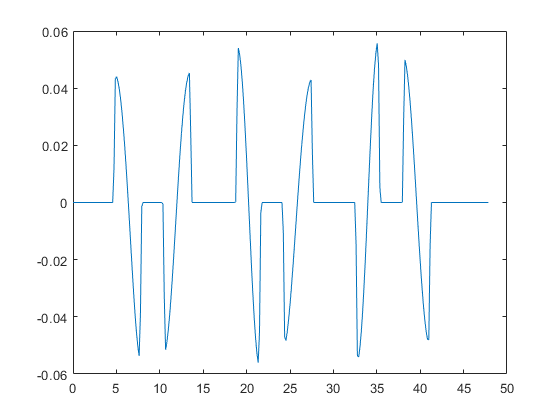

plot(T,yaw_rate);

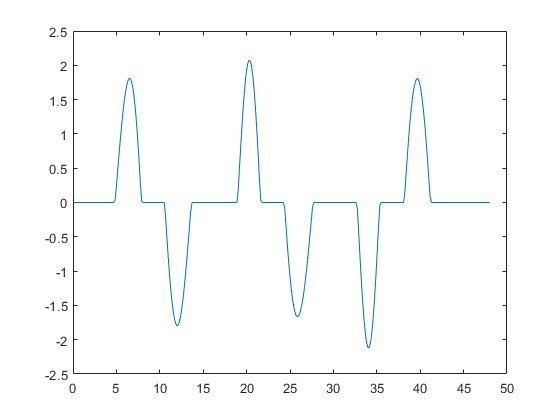

vy = diff_y/0.15238;
plot(T,vy);

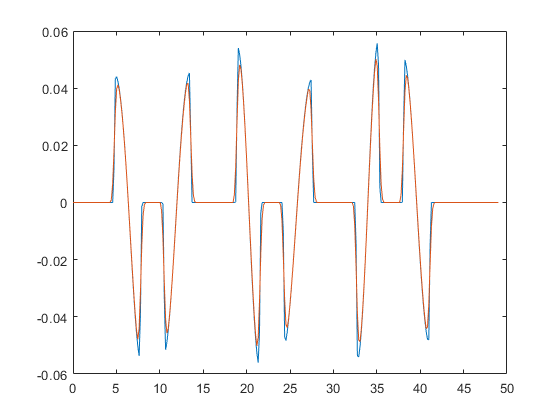

yaw_rate_smooth = smoothdata(yaw_rate,'gaussian',6);
plot(T,yaw_rate,T,yaw_rate_smooth);

ref11 = [T',x',y',yaw',yaw_rate_smooth',vx'/3.6,vy'];

错误使用 horzcat
要串联的数组的维度不一致。

% path5 = [x,y,yaw,yaw_rate_smooth,vy,T,vx];